# 微分约束最小功率算法

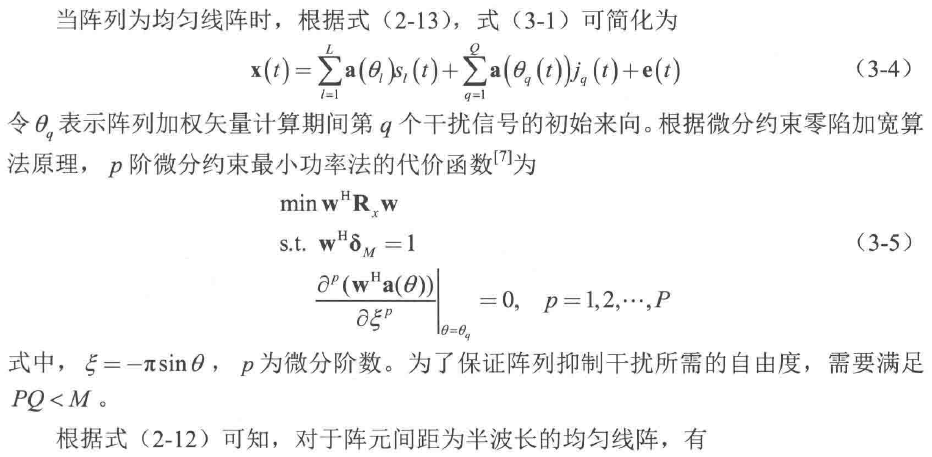

这里并没有解释p阶微分约束的代价函数表示什么意义，-πsinθ表示什么，需要研究一下原理。

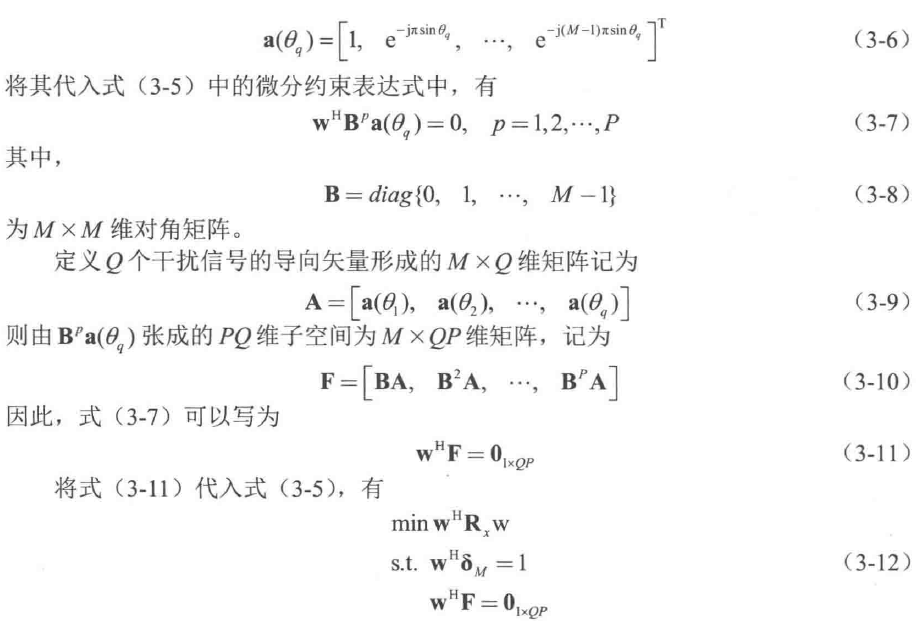

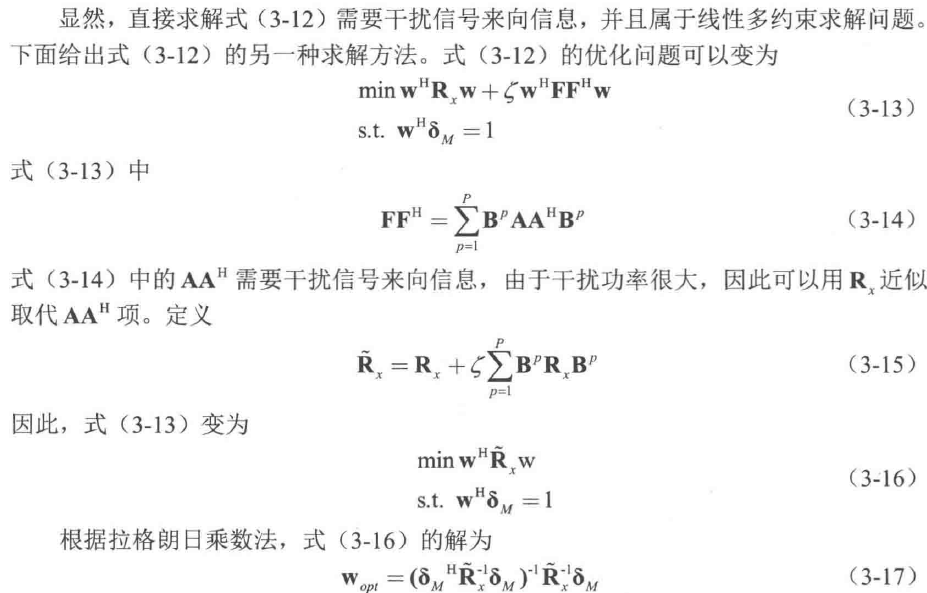

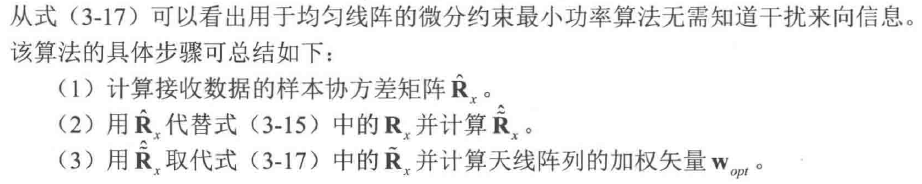

该方法需要满足的条件:MP<N

微分阶数M,干扰源个数P,阵列数N

一般情况下给M=1

参考文献：用于高动态GPS接收机的微分约束最小功率抗干扰方法，写的比较全面

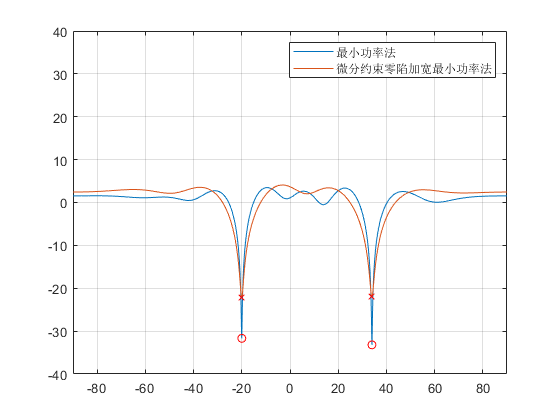

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 8;                                                                     %阵元个数
theta = [-20 34];                                                      %信号 干扰 干扰
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号
S(1,:) = S(1,:).*1;                                                       %信号功率小，干扰功率大,如果信号功率大了 也会默认为干扰位置
X = A*S;                                                                    %对信号来向进行仿真
X1 = awgn(X,snr,'measured');

%--------------------------------------------------------------------------
%   构造接收信号的协方差矩阵
%--------------------------------------------------------------------------
Rx = X1*X1';

%--------------------------------------------------------------------------
%   构造delta_m 约束最小功率
%--------------------------------------------------------------------------
delta_m = zeros(N,1);
delta_m(1) = 1;

%--------------------------------------------------------------------------
%   构造矩阵B
%--------------------------------------------------------------------------
B = diag(0:N-1);

%--------------------------------------------------------------------------
%   第一步,替换Rx
%--------------------------------------------------------------------------
P = 1;                                                                     %确定阶数

%--------------------------------------------------------------------------
%   weight:权重系数，表示P阶微分约束的贡献
%--------------------------------------------------------------------------
weight = 0.0048;

temp = 0;
for p = 1:P
     temp = temp + weight*(B^p)*Rx*(B^p);
end
Rx_tilde = Rx + temp;

%--------------------------------------------------------------------------
%   最优权矢量为
%--------------------------------------------------------------------------
w_opt = (delta_m'*Rx_tilde^-1*delta_m)^-1*(Rx_tilde^-1*delta_m);            %算法输出
w     = (delta_m'*Rx^-1*delta_m)^-1*(Rx^-1*delta_m);                        %原始结果

%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output2(idx) = w_opt'*A1;
    output1(idx) = w'*A1;
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------
for idx = 1:length(theta)
    index(idx) = find([-90:0.1:90]==theta(idx));
end

figure(1)
plot(-90:0.1:90,db(abs(output1)));grid on;
hold on
plot(-90:0.1:90,db(abs(output2)));


plot(theta,db(abs(output1(index))),'ro');
plot(theta,db(abs(output2(index))),'rx');

hold off;
axis([-90 90 -40 40])
legend('最小功率法','微分约束零陷加宽最小功率法')